## F.T

s = tf('s');

## Procesamiento de datos

data = readmatrix('Flujo_delta_25a50.xlsx')

data =    20.0605   25.0000    7.5147
   20.0870   25.0000    7.8209
   20.1135   25.0000    7.6678
   20.1400   25.0000    8.1781
   20.1665   25.0000    7.7698
   20.1930   25.0000    8.0760
   20.2195   25.0000    8.1781
   20.2460   25.0000    8.2291
   20.2725   25.0000    8.5352
   20.2990   25.0000    8.5352


data = readmatrix('Flujo_delta_25a50.xlsx','Range','A377:C1471')

data =    30.0245   25.0000   20.5266
   30.0510   25.0000   20.2205
   30.0775   25.0000   20.4756
   30.1040   25.0000   20.1695
   30.1305   25.0000   20.6797
   30.1570   25.0000   20.1184
   30.1835   25.0000   20.3225
   30.2100   25.0000   19.9653
   30.2365   25.0000   20.2205
   30.2630   25.0000   19.5571


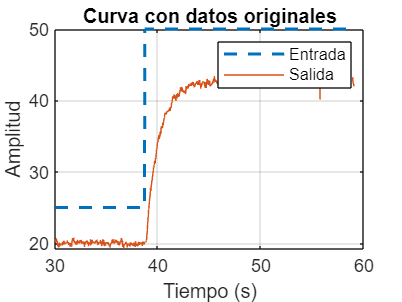


t = data(:,1);
u = data(:,2);
y = data(:,3);


yn = y - mean(y(1:10));
un = u - mean(u(1:10));


figure(1)
plot(t, u,'--', LineWidth=1.5)
hold on
plot(t, y);
title('Curva con datos originales')
legend('Entrada', 'Salida')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
hold off

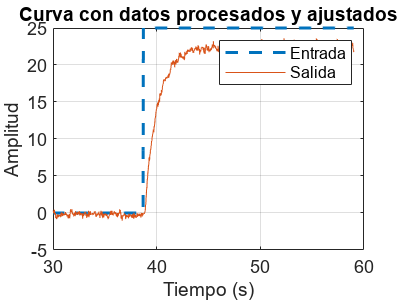


figure(2);
plot(t, un,'--', LineWidth=1.5)
hold on
plot(t, yn);
title('Curva con datos procesados y ajustados')
legend('Entrada', 'Salida')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
hold off

## System Identification Tool

%systemIdentification

#  Simulación con toolbox

s = tf("s");

% Para Toolbox
P1=(0.9058*exp(-0.11419*s))/(1+1.2637*s)

P1 =
 
                    0.9058
  exp(-0.114*s) * -----------
                  1.264 s + 1
 
Continuous-time transfer function.




y1 = lsim(P1,un, t);

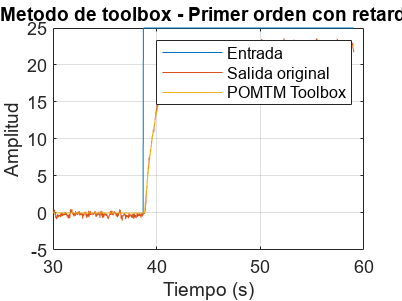



figure(4)
plot(t,un, t, yn, t, y1)
grid on
title("Metodo de toolbox - Primer orden con retardo")
legend('Entrada','Salida original', 'POMTM Toolbox' )
xlabel('Tiempo (s)')
ylabel('Amplitud')

# Calculo del IAE Toolbox

SalidaPlanta= yn;
SalidaModelo_1= y1; % Obtenido con toolbox
e_IAE=abs(SalidaPlanta-SalidaModelo_1);
IAE= trapz(t, e_IAE)

IAE = 8.0495

# Identificación 123c Alfaro Primer orden con retardo

yf = mean(yn(1085:1095))

yf = 22.5397

yi = mean(yn(1:10))

yi = -3.5527e-15


uf = mean(un(1085:1095))

uf = 25

ui = mean(un(1:10)) 

ui = 0


deltay = yf - yi

deltay = 22.5397


deltau = uf - ui

deltau = 25


K = deltay/deltau

K = 0.9016


y25 = 0.25*deltay

y25 = 5.6349

y25_0 = find(yn >= y25, 1) 

y25_0 = 346

t25 = t(y25_0)-38.69

t25 = 0.4770


y75 = 0.75*deltay;
y75_0 = find(yn >= y75, 1) 

y75_0 = 399

t75 = t(y75_0)-38.69

t75 = 1.8815


T = 0.9102*(t75 - t25)

T = 1.2784

L = 1.2620*t25 - 0.2620*t75

L = 0.1090


% Para 123c Alfaro Primer orden con retardo
P1=(K*exp(-L*s))/(1+T*s)

P1 =
 
                    0.9016
  exp(-0.109*s) * -----------
                  1.278 s + 1
 
Continuous-time transfer function.




y1 = lsim(P1,un, t);

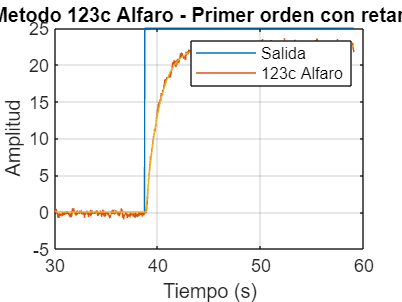


figure(5)
plot(t,un, t, yn, t, y1)
grid on
title("Metodo 123c Alfaro - Primer orden con retardo")
legend('Salida','123c Alfaro')
xlabel('Tiempo (s)')
ylabel('Amplitud')

# Calculo del IAE Alfaro 123c

SalidaPlanta= yn;
SalidaModelo_1= y1; % Obtenido con alfaro
e_IAE=abs(SalidaPlanta-SalidaModelo_1);
IAE= trapz(t, e_IAE)

IAE = 8.4220

# Método de Ho

% Este método utiliza dos puntos 
delta_35 = 0.35*deltay

delta_35 = 7.8889

delta_85 = 0.85*deltay

delta_85 = 19.1587


y35 = delta_35

y35 = 7.8889

y85 = delta_85

y85 = 19.1587


% Se debe buscar el índice del valor solicitado
% Con ese índice se busca en el vector de tiempo
ind_35 = find(yn >= y35,1)  

ind_35 = 353

% Al tiempo correspondiente al índice se le resta un dato
t35 = t(ind_35)-38.69   %Modelo más preciso con 320 datos de tiempo antes     

t35 = 0.6625

ind_85 = find(yn >= y85,1)

ind_85 = 427

t85 = t(ind_85)-38.69   %Modelo más preciso con 320 datos de tiempo antes

t85 = 2.6235


a=-0.670;b=0.670;
c=1.300;d=-0.290;
tau = a*t35 + b*t85

tau = 1.3139

tm = c*t35 + d*t85

tm = 0.1004


figure(1)
P_dp = K*exp(-tm*s)/(tau*s+1)

P_dp =
 
                  0.9016
  exp(-0.1*s) * -----------
                1.314 s + 1
 
Continuous-time transfer function.



POMTM_Ho = lsim(P_dp,un,t);

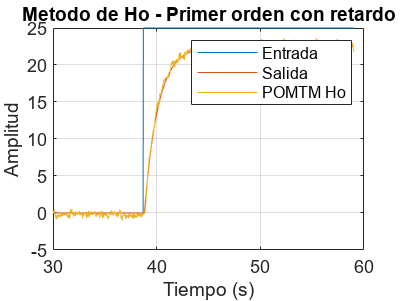


figure(6)
plot(t, un, t,POMTM_Ho, t, yn)
title("Metodo de Ho - Primer orden con retardo")
grid on
legend('Entrada', 'Salida','POMTM Ho')
xlabel('Tiempo (s)')
ylabel('Amplitud')

# **IAE método Ho**

SalidaPlanta= yn;
SalidaModelo_1= POMTM_Ho; % Obtenido con toolbox
e_IAE=abs(SalidaPlanta-SalidaModelo_1);
IAE=trapz(t,e_IAE)

IAE = 8.6932

# Comparación de modelos

figure(7)
title("Compración de modelos")
plot(t, un, t,POMTM_Ho, t, yn)